# ** ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} \mathbb{E}_0\left(U\right) =  \mathbb{E}_0\left[\sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma}\right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$ and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. You will gradually extend, solve, and simulate this model. When simulating the model, initialize the state variables, including age: for the endogenous state variables, assume equal probabilities for each state; for any exogenous Markov process, draw from the stationary distribution. In each simulation, you must have a panel of 1000 consumers over 30 periods. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_0\left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta \left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/nguyenhoangminh/Desktop/ps2 - task 1'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is /Users/nguyenhoangminh/Desktop/ps2 - task 1 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.9500 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

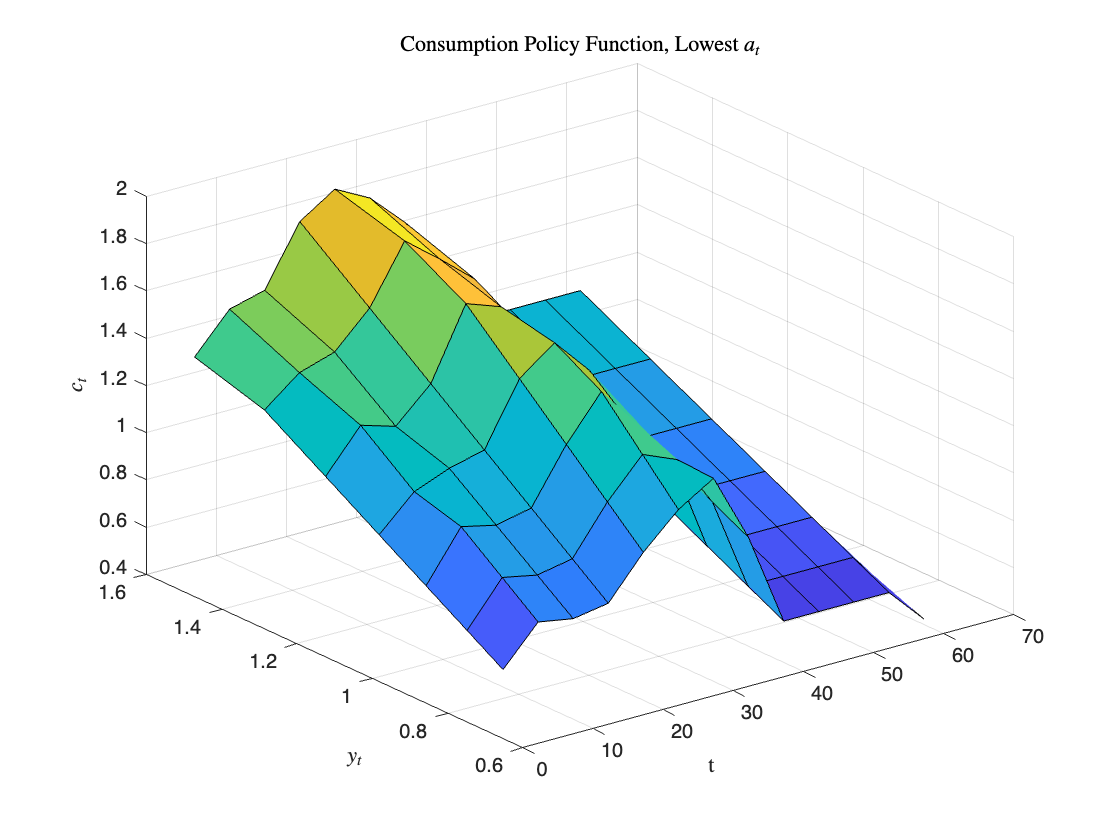

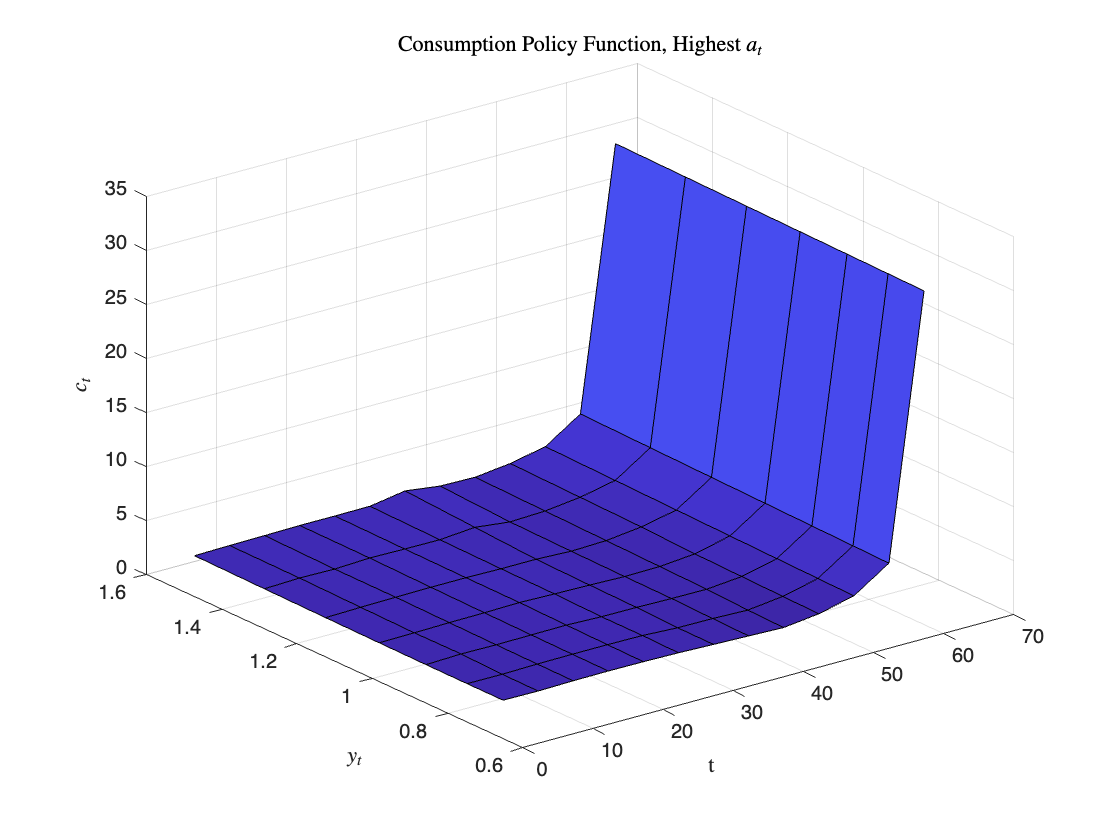

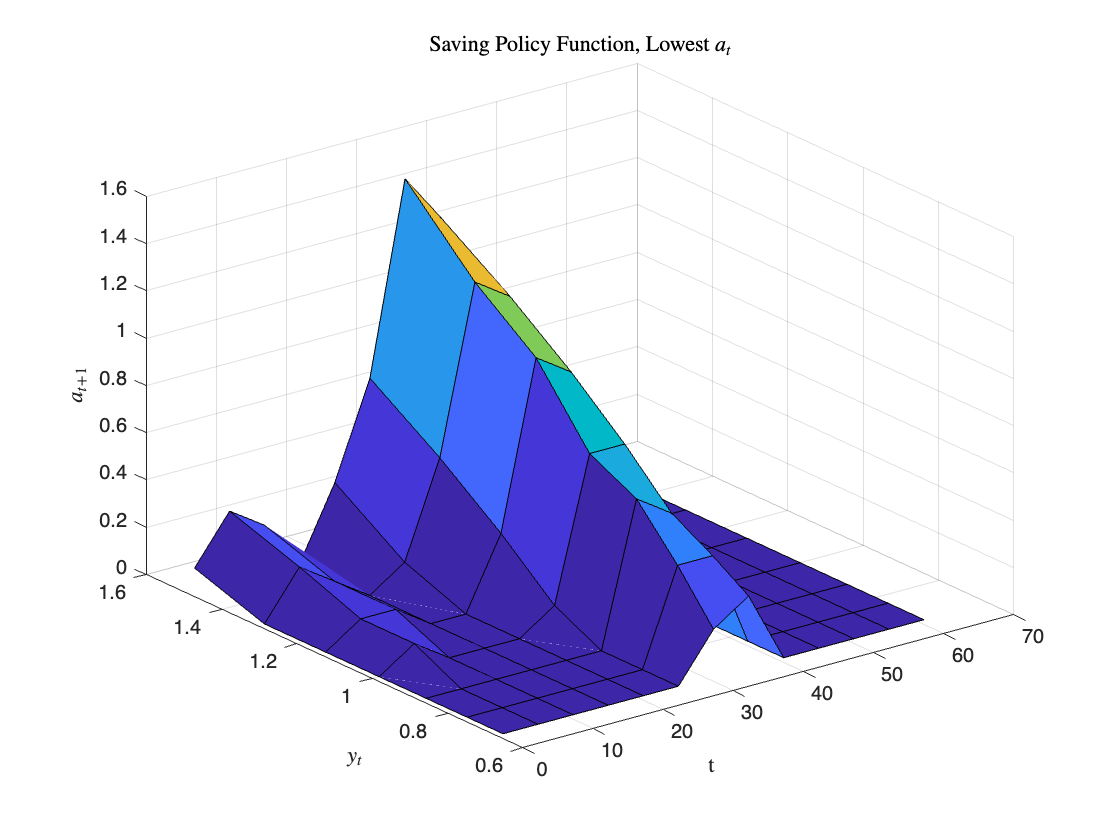

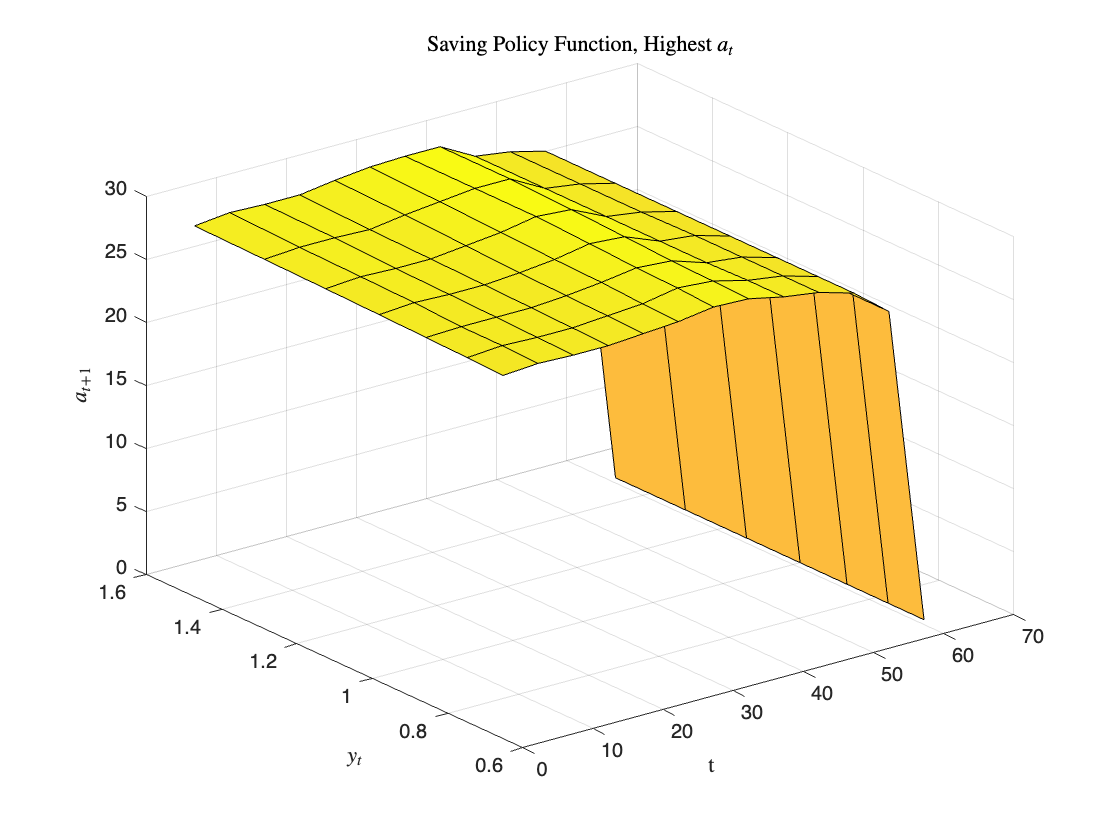

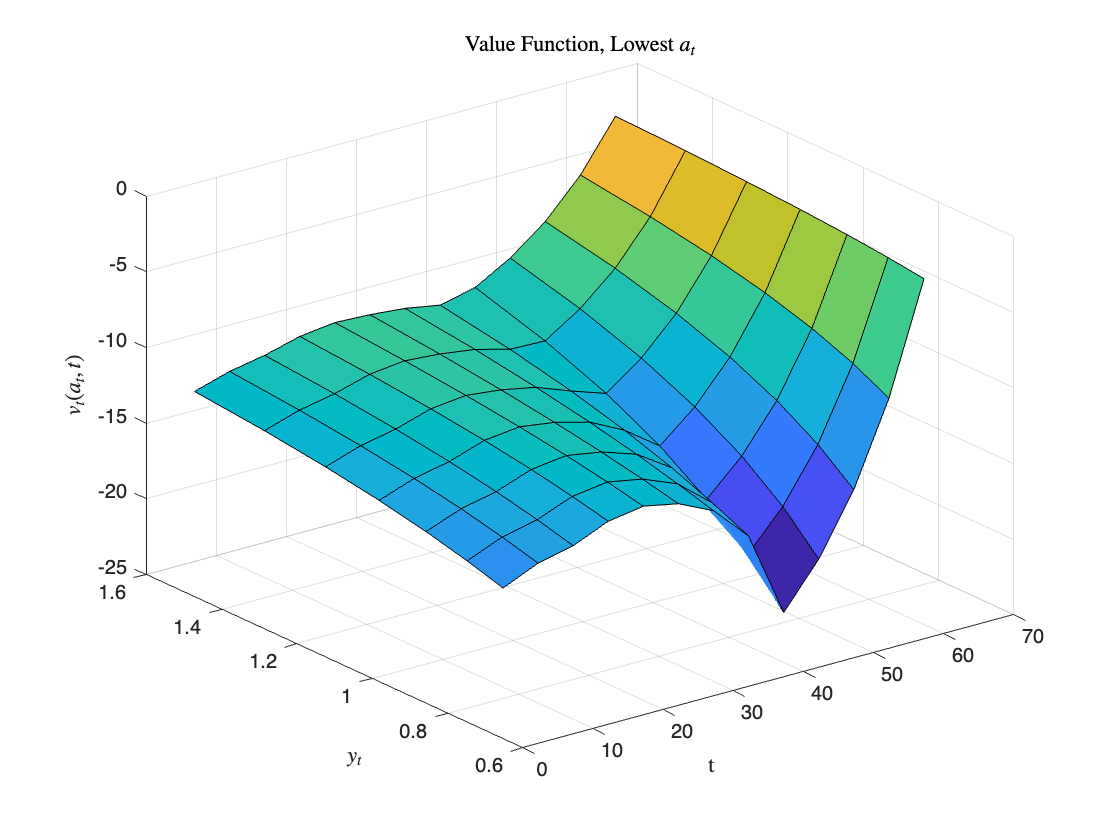

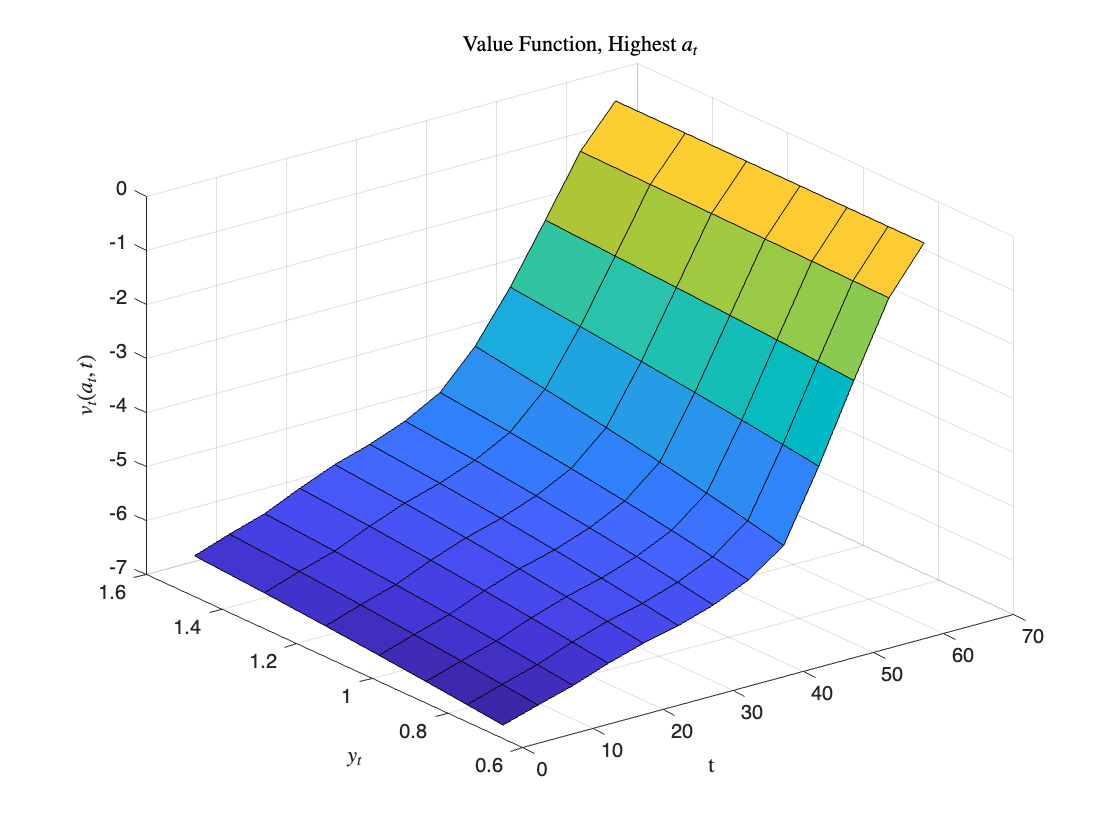

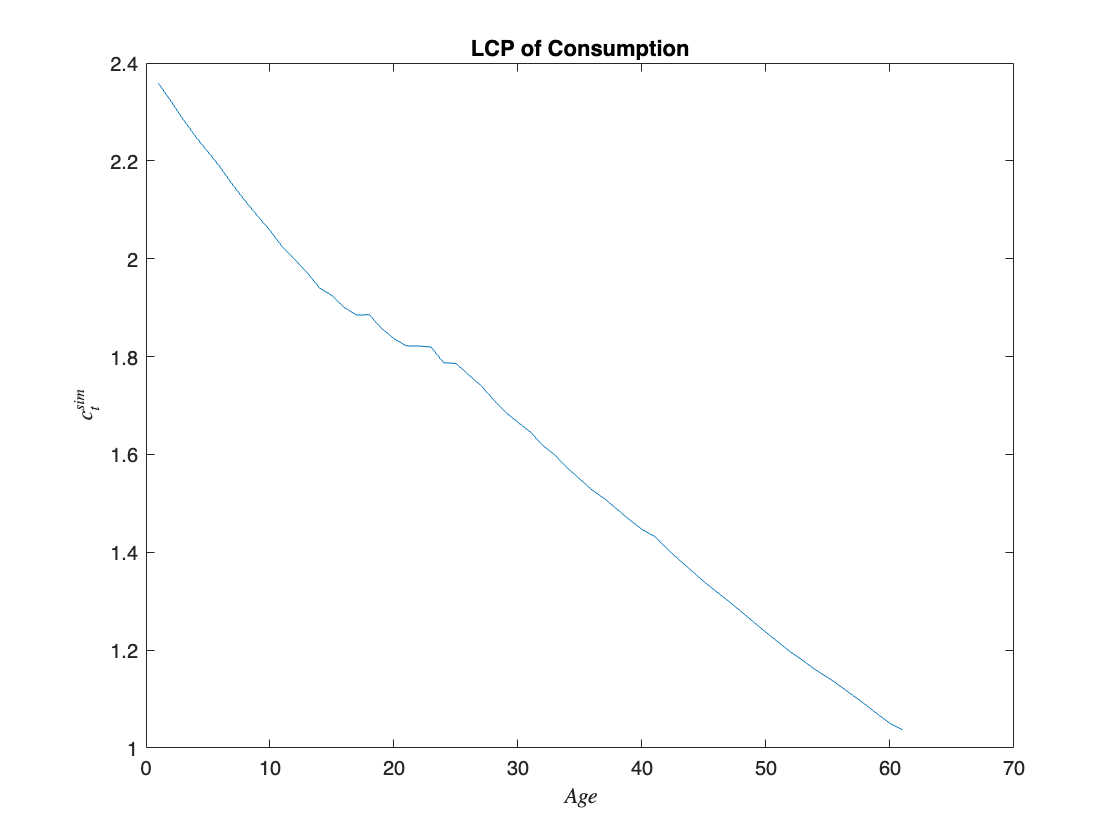

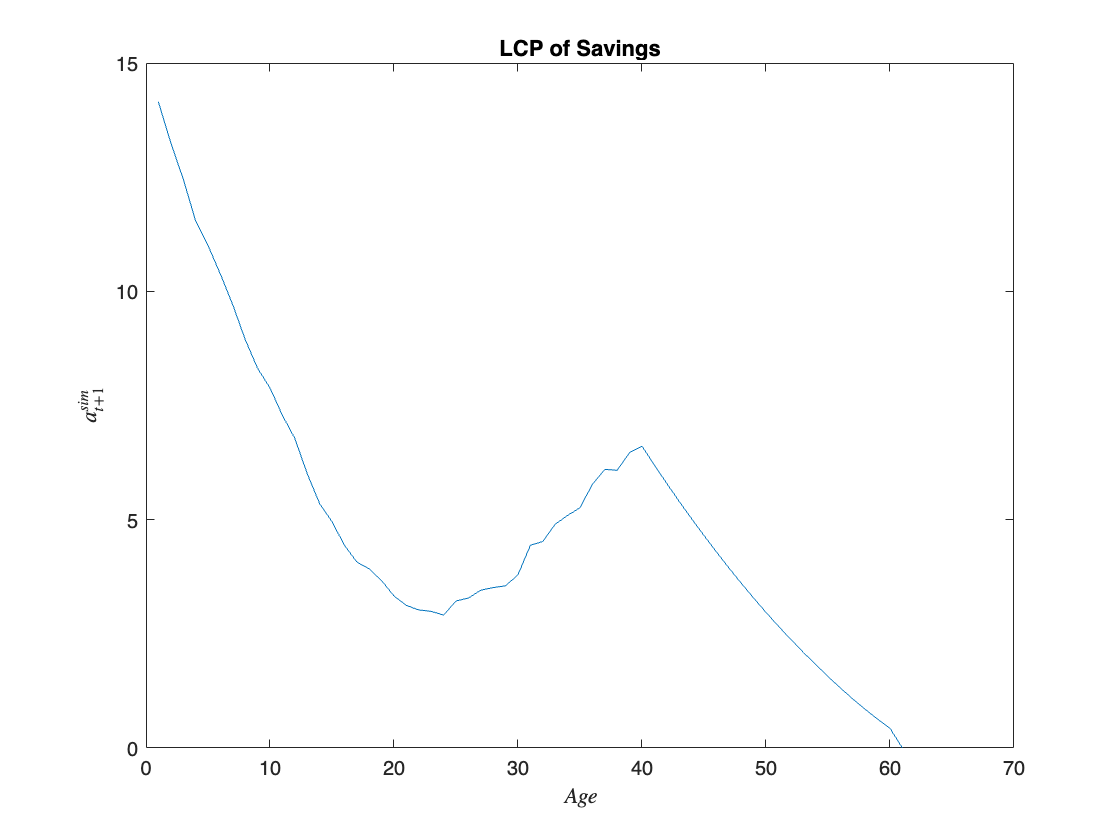

sim = simulate.lc(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.

beta_vals = [0.90, 0.92, 0.94, 0.96];
gamma_fixed = 2.00;

% Load base model
par0 = model.setup();
par0 = model.gen_grids(par0);
ages = 1:par0.T;

fprintf('Descriptive stats by β (γ = %.2f):\n', gamma_fixed);

Descriptive stats by β (γ = 2.00):


fprintf(['  β     | Mean(C)  Min(C)   Max(C)   Std(C)  || ' ...
                'Mean(A)  Min(A)   Max(A)   Std(A)\n']);

  β     | Mean(C)  Min(C)   Max(C)   Std(C)  || Mean(A)  Min(A)   Max(A)   Std(A)


fprintf([repmat('-', 1, 83) '\n']);

-----------------------------------------------------------------------------------



figure(1); clf;

for i = 1:length(beta_vals)
    par = par0;
    par.beta = beta_vals(i);
    par.sigma = gamma_fixed;

    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Life-Cycle Profiles
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), "omitnan");
        lcp_a(t) = mean(sim.asim(sim.tsim == t), "omitnan");
    end

    mean_c = mean(lcp_c, 'omitnan');
    min_c = min(lcp_c, [], 'omitnan');
    max_c = max(lcp_c, [], 'omitnan');
    std_c = std(lcp_c, 'omitnan');

    mean_a = mean(lcp_a, 'omitnan');
    min_a = min(lcp_a, [], 'omitnan');
    max_a = max(lcp_a, [], 'omitnan');
    std_a = std(lcp_a, 'omitnan');

    % Print results
    fprintf(' %.2f   | %.4f  %.4f  %.4f  %.4f  || %.4f  %.4f  %.4f  %.4f\n', ...
        par.beta, mean_c, min_c, max_c, std_c, ...
        mean_a, min_a, max_a, std_a);

    subplot(2,1,1); hold on;
    plot(ages, lcp_c, 'DisplayName', sprintf('\\beta = %.2f', par.beta));

    subplot(2,1,2); hold on;
    plot(ages, lcp_a, 'DisplayName', sprintf('\\beta = %.2f', par.beta));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 0.90   | 1.5507  0.7161  2.8934  0.5619  || 1.9793  0.0000  13.5982  3.2686


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 0.92   | 1.5719  0.7683  2.6579  0.5104  || 2.7082  0.0000  13.8407  3.3696


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 0.94   | 1.6389  1.0378  2.3586  0.3730  || 5.0091  0.0000  14.1490  3.1461


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 0.96   | 1.7548  1.5069  1.9982  0.1399  || 8.9867  0.0000  14.5203  3.2390


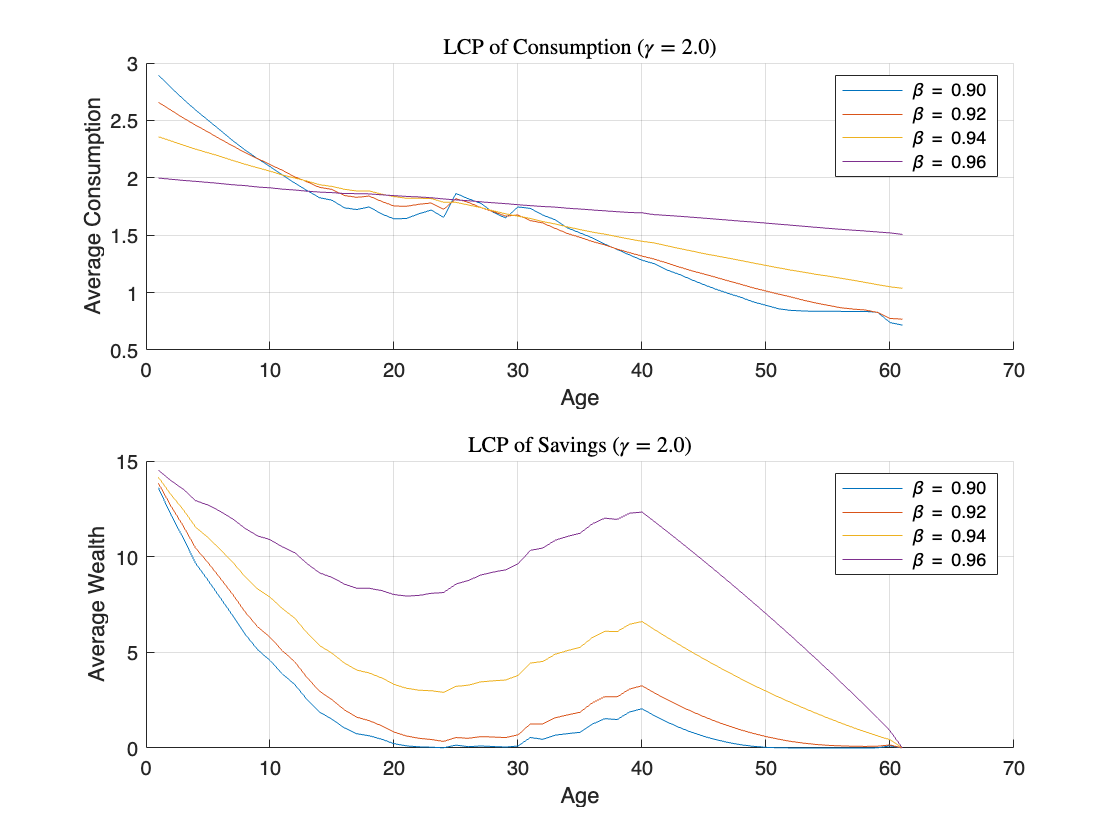


% Final plot touches for β variation
subplot(2,1,1);
title('LCP of Consumption ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Consumption'); grid on; legend show;

subplot(2,1,2);
title('LCP of Savings ($\gamma = 2.0$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Wealth'); grid on; legend show;


drawnow;


%% ------------ Varying γ (Fixed β = 0.94) ------------ %%
gamma_vals = [2.00, 3.00, 4.00, 5.00];
beta_fixed = 0.96;

% Reload base model to avoid carry-over issues
par1 = model.setup();
par1 = model.gen_grids(par1);
ages = 1:par1.T;

fprintf('\nDescriptive stats by γ (β = %.2f):\n', beta_fixed);


Descriptive stats by γ (β = 0.96):


fprintf(['  γ     | Mean(C)  Min(C)   Max(C)   Std(C)  || ' ...
                'Mean(A)  Min(A)   Max(A)   Std(A)\n']);

  γ     | Mean(C)  Min(C)   Max(C)   Std(C)  || Mean(A)  Min(A)   Max(A)   Std(A)


fprintf([repmat('-', 1, 83) '\n']);

-----------------------------------------------------------------------------------



figure(2); clf;

for j = 1:length(gamma_vals)
    par = par1;
    par.beta = beta_fixed;
    par.sigma = gamma_vals(j);

    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Life-Cycle Profiles
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), "omitnan");
        lcp_a(t) = mean(sim.asim(sim.tsim == t), "omitnan");
    end

    mean_c = mean(lcp_c, 'omitnan');
    min_c = min(lcp_c, [], 'omitnan');
    max_c = max(lcp_c, [], 'omitnan');
    std_c = std(lcp_c, 'omitnan');

    mean_a = mean(lcp_a, 'omitnan');
    min_a = min(lcp_a, [], 'omitnan');
    max_a = max(lcp_a, [], 'omitnan');
    std_a = std(lcp_a, 'omitnan');

    % Print results
    fprintf(' %.2f   | %.4f  %.4f  %.4f  %.4f  || %.4f  %.4f  %.4f  %.4f\n', ...
        par.sigma, mean_c, min_c, max_c, std_c, ...
        mean_a, min_a, max_a, std_a);

    subplot(2,1,1); hold on;
    plot(ages, lcp_c, 'DisplayName', sprintf('\\gamma = %.2f', par.sigma));

    subplot(2,1,2); hold on;
    plot(ages, lcp_a, 'DisplayName', sprintf('\\gamma = %.2f', par.sigma));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 2.00   | 1.7548  1.5069  1.9982  0.1399  || 8.9867  0.0000  14.5203  3.2390


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 3.00   | 1.7825  1.6250  1.9255  0.0841  || 9.9365  0.0000  14.5951  3.3952


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 4.00   | 1.7981  1.6888  1.8888  0.0526  || 10.4745  0.0000  14.6329  3.5044


------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


 5.00   | 1.8085  1.7331  1.8610  0.0322  || 10.8301  0.0000  15.0679  3.5845


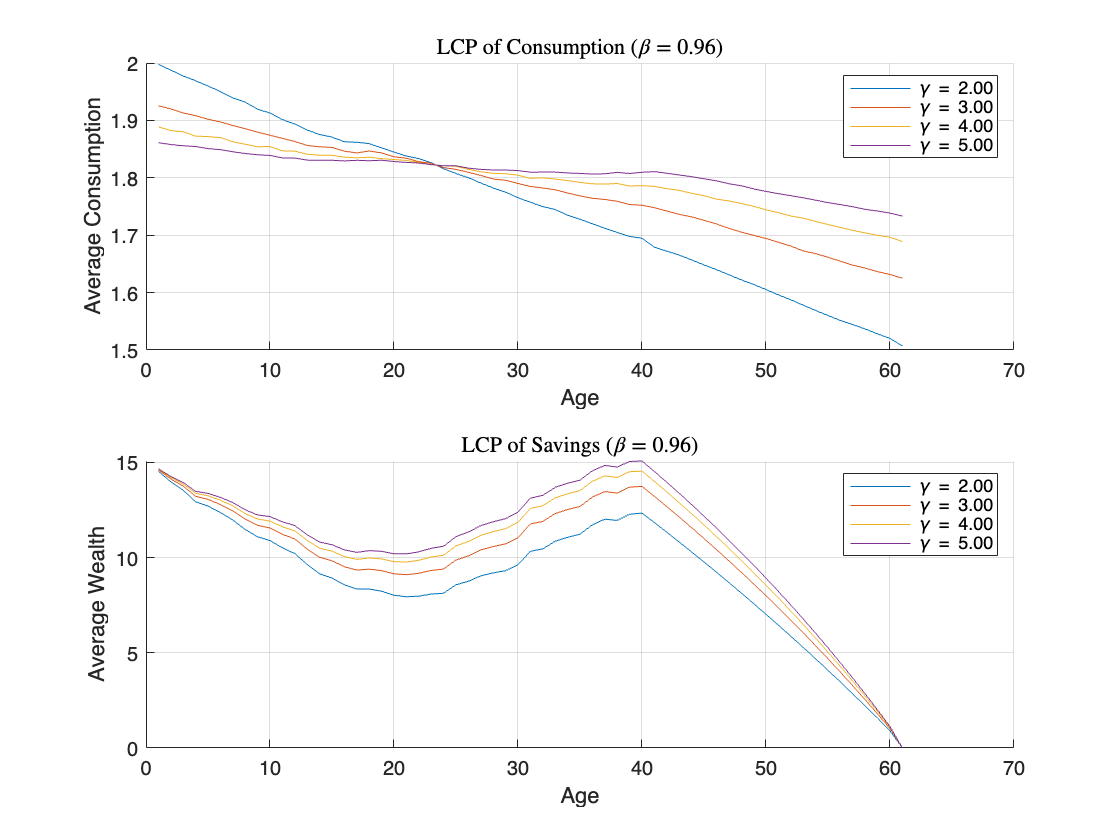


% Final plot touches for γ variation
subplot(2,1,1);
title('LCP of Consumption ($\beta = 0.96$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Consumption'); grid on; legend show;

subplot(2,1,2);
title('LCP of Savings ($\beta = 0.96$)', 'Interpreter', 'latex');
xlabel('Age'); ylabel('Average Wealth'); grid on; legend show;


drawnow;


avg_wealth_matrix = zeros(length(beta_vals), length(gamma_vals));
for i = 1:length(beta_vals)
    for j = 1:length(gamma_vals)
        par = par0;
        par.beta = beta_vals(i);
        par.sigma = gamma_vals(j);

        sol = solve.lc(par);
        sim = simulate.lc(par, sol);

        avg_wealth = mean(sim.asim(:), "omitnan");
        avg_wealth_matrix(i, j) = avg_wealth;
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

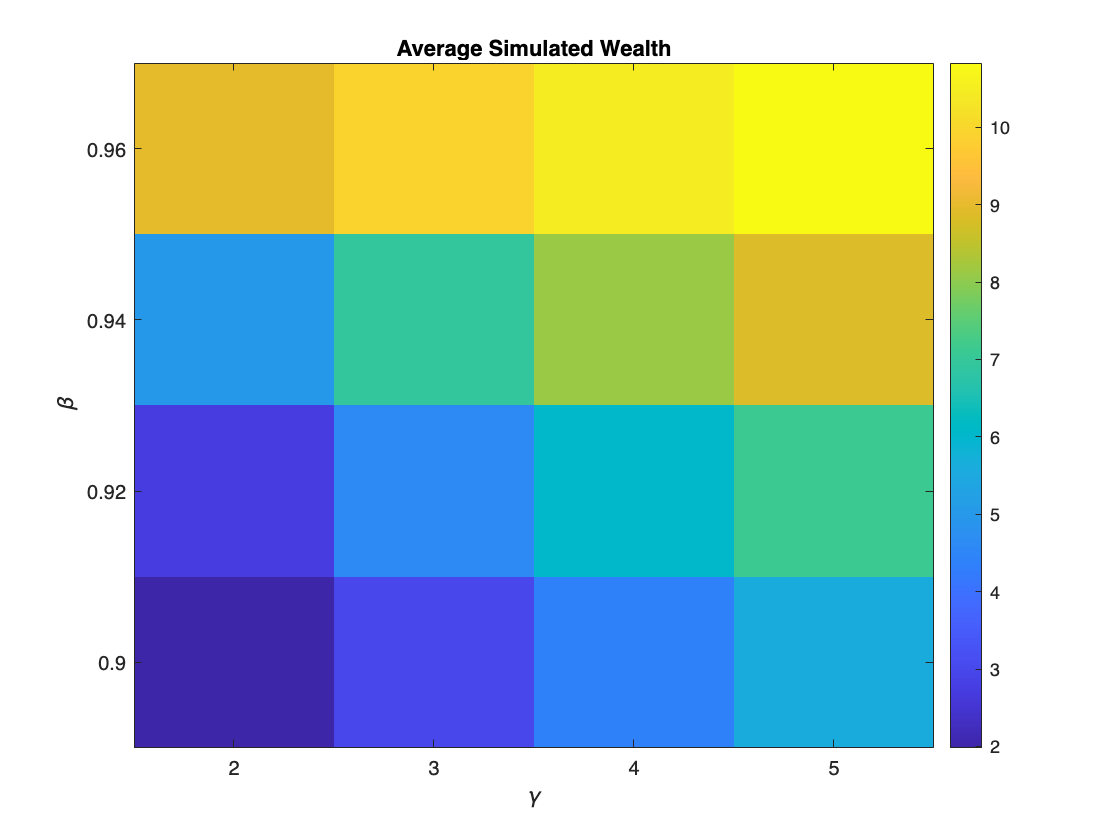


% Plot heat map
figure;
imagesc(gamma_vals, beta_vals, avg_wealth_matrix);
colorbar;
xlabel('\gamma'); ylabel('\beta');
title('Average Simulated Wealth');
set(gca, 'YDir', 'normal');  % Flip Y-axis so lowest beta is at bottom
xticks(gamma_vals); yticks(beta_vals);